Name: Mukesh Aryal

Student ID: 268456

u=eps/2

u = 1.1102e-16

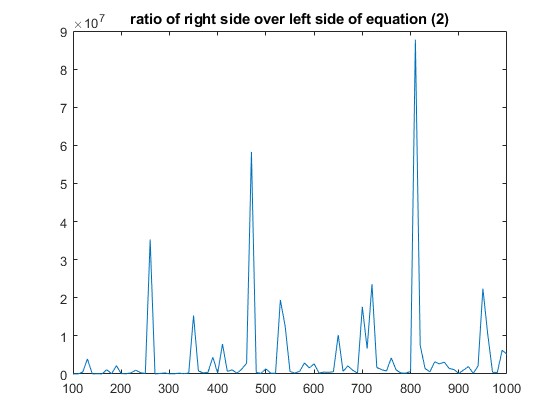

ratios=[];
for n=100:10:1000     
    
    A=randi([-10,10],n);
    x_e=ones(n,1);
    b=A*x_e;
    x=A\b;
    left=norm(x-x_e,'inf')/norm(x,'inf'); % inf using cond does not work for vectors.
    right=u*cond(A,'inf')*cond(inv(A),'inf');
    val=right/left;
    ratios=[ratios; val];
end
plot(100:10:1000,ratios);
title('ratio of right side over left side of equation (2)');

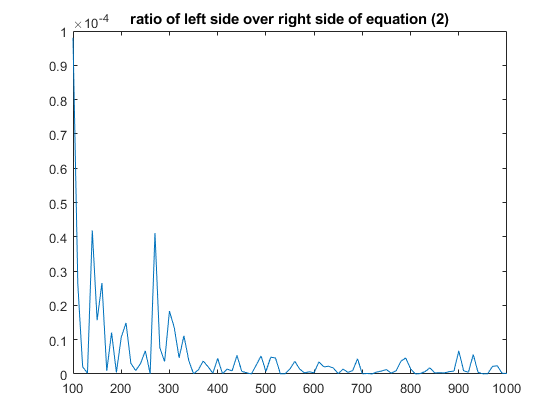

plot(100:10:1000,1./ratios);
title('ratio of left side over right side of equation (2)');